clear all
close all

addpath("Immagini\06_binning")

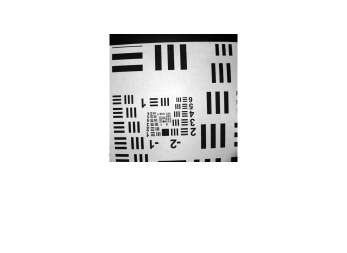

im_1 = importdata("Risoluzione_B8_t0313_f4.asc");
im_1 = im_1(:,2:end);

noise_1 = importdata("Risoluzione_buio_B8_t0313_f4.asc");
noise_1 = noise_1(:,2:end);

im_1 = im_1 - noise_1;

imshow(im_1,[])

x = [54  60];
y = [-102 -102];

pixel_dist = round(sqrt((x(1)-x(2))^2 + (y(1)-y(2))^2))

pixel_dist = 6

conv_factor = pixel_dist/10 % pixel/mm

conv_factor = 0.6000

close all hidden;

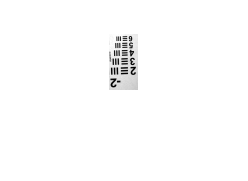

group_m2 = im_1(62:117,61:89);
imshow(group_m2, [])

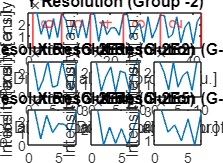


subplot(3,3,[1,2,3]);
y_resm2 = improfile(group_m2, [16 16], [1 42]);
plot(y_resm2)
title("Y Resolution (Group -2)")
ylabel("Pixel Intensity [a.u.]")
xlabel("Distance along y profile [a.u.]")
xline(42, 'LineWidth', 1, 'Color', 'r')
xline(32, 'LineWidth', 1, 'Color', 'r', 'Label', '2')
xline(23, 'LineWidth', 1, 'Color', 'r', 'Label', '3')
xline(15, 'LineWidth', 1, 'Color', 'r', 'Label', '4')
xline(8, 'LineWidth', 1, 'Color', 'r', 'Label', '5')
xline(1, 'LineWidth', 1, 'Color', 'r', 'Label', '6')

subplot(3,3,4);
x_resm21 = improfile(im_1, [52 61], [69 69]);
plot(x_resm21)
title("X Resolution (G-2E1)")
ylabel("Pixel Intensity [a.u.]")
xlabel("Distance along x profile [a.u.]")

subplot(3,3,5);
x_resm22 = improfile(group_m2, [2 11], [37 37]);
plot(x_resm22)
title("X Resolution (G-2E2)")
ylabel("Pixel Intensity [a.u.]")
xlabel("Distance along x profile [a.u.]")

subplot(3,3,6);
x_resm23 = improfile(group_m2, [3 11], [29 29]);
plot(x_resm23)
title("X Resolution (G-2E3)")
ylabel("Pixel Intensity [a.u.]")
xlabel("Distance along x profile [a.u.]")

subplot(3,3,7);
x_resm24 = improfile(group_m2, [5 12], [19 19]);
plot(x_resm24)
title("X Resolution (G-2E4)")
ylabel("Pixel Intensity [a.u.]")
xlabel("Distance along x profile [a.u.]")

subplot(3,3,8);
x_resm25 = improfile(group_m2, [6 13], [12 12]);
plot(x_resm25)
title("X Resolution (G-2E5)")
ylabel("Pixel Intensity [a.u.]")
xlabel("Distance along x profile [a.u.]")

subplot(3,3,9);
x_resm26 = improfile(group_m2, [7 13], [5 5]);
plot(x_resm26)
title("X Resolution (G-2E6)")
ylabel("Pixel Intensity [a.u.]")
xlabel("Distance along x profile [a.u.]")

group_y = -2;
element_y = 6;

r_y = 2^(group_y+(element_y-1)/6);
R_y = 1/r_y

R_y = 2.2449


group_x = -2;
element_x = 6;

r_x = 2^(group_x+(element_x-1)/6);
R_x = 1/r_x

R_x = 2.2449

half = @(x) round(x/2);